# Analysis and Classification of RPS Data

#### Pris Morales & Aissa Conde

*****Note****** Code below was introduced in prior assignments. Some modifications have been made to work best for our use case.*

# Offline Classification From Features

Neurotechnology, Brains and Machines 2023 (shell code my Sam Michalka)

This shell code expects that you have:

-  data with features already extracted in a variable called feature_table

- gesturelist for the data in a variable called gesturelist. 

The features should be in a table with the rows equal to the number of trials and the columns equal to the number of features. You can select a subset of features in the code below.

clear

Indicate if your test data is in a separate file or partitioned from the train data.

Make a list of files to load. If this has two things, the code will assume it is the train features followed by the test features. If it has one item, it will assume they are training featues and run a train-test split.  

If you want to use resubstitution, put the same training data twice (once as train, once as test).

%filesToLoad = {"latest_feature_table.mat"}; % you'll need to change this name

%filesToLoad = {"latest_feature_table.mat","latest_feature_table.mat"}; %Do this for resubstitution

%filesToLoad = {"train_feature_table.mat", "test_feature_table.mat"};
%filesToLoad = {"train_feature_table.mat"};

filesToLoad = {"trainrps_feature_table.mat", "trainrps_feature_table.mat"};

#### Select which features you want. selected_features is the indices of these features. You can get fancy and use contains() if you want to pull them out by name.

% temporarily load the feature data to get selected features
load(filesToLoad{1})

Print out all the feature names

feature_table.Properties.VariableNames

ans = 1×12 cell array
    {'var_Ch1'}    {'var_Ch2'}    {'var_Ch3'}    {'var_Ch4'}    {'meanabs_Ch1'}    {'meanabs_Ch2'}    {'meanabs_Ch3'}    {'meanabs_Ch4'}    {'rms_Ch1'}    {'rms_Ch2'}    {'rms_Ch3'}    {'rms_Ch4'}


Select a subset of features (or all of them)

selected_features = 1:size(feature_table,2); % This selects all features
%selected_features = [1 2]; %This selects the first two features listed above
%selected_features = [1 2 3 4];

clearvars feature_table gesturelist  % you just temporarily loaded these in to
%get the feature names, delete them so you don't get confused

## Load the feature data and put into X and y matrices

Look inside the function below to set things like train-test split.

[X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features);


## Build a classifier and do k-fold cross-validation

% Perform cross-validation
KFolds = 5;
cvp_kfold = cvpartition(y_train, 'KFold', KFolds);

% Make empty vector to store predictions from k-fold cross-validation
validation_predictions = NaN(length(y_train),1);

% Loop through all the folds
for fold = 1:KFolds
    % Within each partition, assign the data for that fold to the
    % cross-validation training data
    kfold_partial_data_X_train = X_train(cvp_kfold.training(fold), :);
    kfold_partial_data_y_train = y_train(cvp_kfold.training(fold), :);
    
    % Within each partition, assign the data for that fold to the
    % cross-validation validation (testing) data
    kfold_partial_data_X_val = X_train(cvp_kfold.test(fold), :);
    %kfold_partial_data_y_val = y_train(cvp_kfold.test(fold), :);

    % Build a temporary model for this subset of the data (k-1)/k
    kfold_classifier = createClassifier(kfold_partial_data_X_train,kfold_partial_data_y_train);

    % Make predictions with the kfold_classifier  (temporary classifier on
    % subset of data)
    kfold_predictions = kfold_classifier.predict(kfold_partial_data_X_val);

    % Store predictions in the original order
    validation_predictions(cvp_kfold.test(fold), :) = kfold_predictions;
end

% Calculate cross-validation metrics
[validation_accuracy ] = calculateMetrics(y_train, validation_predictions)

validation_accuracy = 0.9564

## Build a classifer on all of the training data

By making a createClassifier function, we can better ensure that the classifier we're using for the model and for cross-validation are the same. You can also make this into a function with other options (like which classifier to use or some paramter in the classifier that you want to vary).

% Create a classifier  
currentClassifier = createClassifier(X_train, y_train);

## Use classifier to predict on training data (resubstitution)

y_train_predictions = currentClassifier.predict(X_train);
[train_accuracy ] = calculateMetrics(y_train, y_train_predictions)

train_accuracy = 0.9597

% Display results
disp('Cross-Validation Accuracy:');

Cross-Validation Accuracy:


disp(validation_accuracy);

    0.9564




disp('Resubstitution Accuracy:');

Resubstitution Accuracy:


disp(train_accuracy);

    0.9597



clear all;
filesToLoad = {"trainrps_feature_table.mat"};
load(filesToLoad{1});

% Define feature types and their corresponding indices
feature_types = {'Variance', 'MeanAbs', 'RootMS'};
feature_indices = 1:size(feature_table,2);

% Initialize a cell array to store results for each feature type
results = cell(length(feature_types), 2); % 2 columns for Cross-Validation Accuracy and Resubstitution Accuracy

% Loop over each feature type
for type_idx = 1:length(feature_types)
    % Select features for the current feature type
    selected_features = feature_indices(type_idx);

    % Create X_train, y_train, X_test, and y_test
    [X_train, y_train, ~, ~] = featuresTo_X_y_train_test(filesToLoad, selected_features);

    % Perform cross-validation
    KFolds = 5;
    cvp_kfold = cvpartition(y_train, 'KFold', KFolds);

    % Make empty vector to store predictions from k-fold cross-validation
    validation_predictions = NaN(length(y_train), 1);

    % Loop through all the folds
    for fold = 1:KFolds
        kfold_partial_data_X_train = X_train(cvp_kfold.training(fold), :);
        kfold_partial_data_y_train = y_train(cvp_kfold.training(fold), :);

        kfold_partial_data_X_val = X_train(cvp_kfold.test(fold), :);

        kfold_classifier = createClassifier(kfold_partial_data_X_train, kfold_partial_data_y_train);

        kfold_predictions = kfold_classifier.predict(kfold_partial_data_X_val);

        validation_predictions(cvp_kfold.test(fold), :) = kfold_predictions;
    end

    % Calculate cross-validation metrics
    [validation_accuracy] = calculateMetrics(y_train, validation_predictions);

    % Build a classifier on all of the training data
    currentClassifier = createClassifier(X_train, y_train);

    % Use the classifier to predict on training data (resubstitution)
    y_train_predictions = currentClassifier.predict(X_train);
    [train_accuracy] = calculateMetrics(y_train, y_train_predictions);

    % Store results
    results{type_idx, 1} = validation_accuracy;
    results{type_idx, 2} = train_accuracy;
end

Making new training-test partiton
loading prior training-test partition


loading prior training-test partition


% Display results
disp('Results for Different Feature Types:');

Results for Different Feature Types:


disp('Feature Type | Cross-Validation Accuracy | Resubstitution Accuracy');

Feature Type | Cross-Validation Accuracy | Resubstitution Accuracy


for type_idx = 1:length(feature_types)
    fprintf('%12s | %23.4f | %21.4f\n', feature_types{type_idx}, results{type_idx, 1}, results{type_idx, 2});
end

    Variance |                  0.7545 |                0.7545
     MeanAbs |                  0.5893 |                0.5000
      RootMS |                  0.6696 |                0.6295


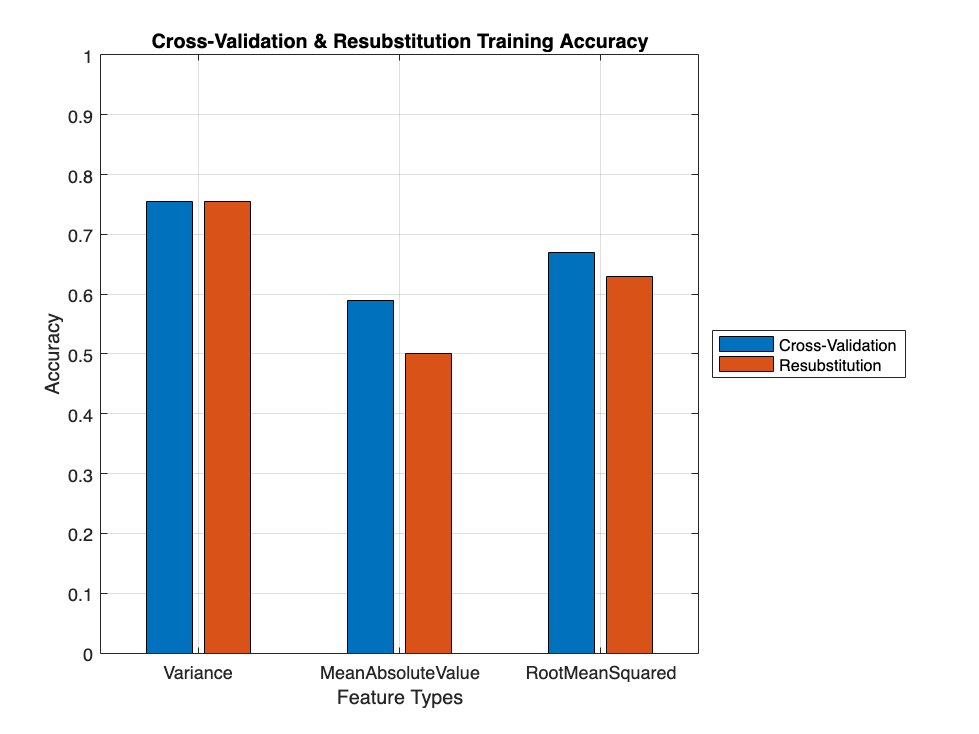

% Assuming 'results' is a 4x2 cell containing accuracies
% Each row corresponds to a feature type, and each column is either Cross-Validation or Resubstitution Accuracy

% Extract accuracy values
crossValidationAccuracies = cell2mat(results(:, 1));
resubstitutionAccuracies = cell2mat(results(:, 2));

% Feature types
feature_types = {'Variance', 'MeanAbsoluteValue', 'RootMeanSquared', 'Range'};

% Create a bar graph
figure;
bar([crossValidationAccuracies, resubstitutionAccuracies]);

% Customize the plot
title('Cross-Validation & Resubstitution Training Accuracy');
xlabel('Feature Types');
ylabel('Accuracy');
legend('Cross-Validation', 'Resubstitution', 'Location', 'eastoutside');
set(gca, 'xticklabel', feature_types);
ylim([0 1]); % Set the y-axis limits between 0 and 1

% Show grid
grid on;

## Use classifier to predict on test data

% Define the selected features for the final model
selected_features_final = 1:size(feature_table,2);
% Extract the selected features
X_final = feature_table(:, selected_features_final);

% Split the data into training and test sets
[X_train_final, y_train_final, X_test_final, y_test_final] = featuresTo_X_y_train_test({'trainrps_feature_table.mat', 'trainrps_feature_table.mat'}, selected_features_final);

% Build the final classifier
finalClassifier = createClassifier(X_train_final, y_train_final);

% Predict on training data (resubstitution)
y_train_pred_final = finalClassifier.predict(X_train_final);
[train_accuracy_final] = calculateMetrics(y_train_final, y_train_pred_final);

% Predict on test data
y_test_pred_final = finalClassifier.predict(X_test_final);
[test_accuracy_final] = calculateMetrics(y_test_final, y_test_pred_final);

% Display the accuracy table
accuracy_table_final = table(train_accuracy_final, test_accuracy_final, 'VariableNames', {'Training_Accuracy', 'Test_Accuracy'});
disp(accuracy_table_final);

    Training_Accuracy    Test_Accuracy
    _________________    _____________

         0.95973            0.95973   



# Helper functions

The code after this are functions that you can use and modify. By using functions to do more of the detailed work, we can better see the big picture above. And, we can better reuse the same code.

## Create X_train, y_train, X_test, and y_test. Configure train-test split here.

function [X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features)


True if you have separate test data to load (or just use all the train data again), false if you want to partition it from the data.

    if size(filesToLoad,2) == 2
        isSeparateTestData = true;
    elseif size(filesToLoad,2) == 1
        isSeparateTestData = false;
    else 
        error("Wrong number of files to load.")
    end
    
    %

Load the training data. This is expecting your features to be in a table called feature_table. 

    load(filesToLoad{1})

#### If separate test data

    if isSeparateTestData   
        % Put the train data into X and y  
        X_train = feature_table(:,selected_features);
        y_train = gesturelist;
    
    
        % If you just want to use your train data again (resubstitution), just
        % get rid of the load part and repeat the step above.
    
        % Load the test data (here, it's the same file.. so fix this)
        load(filesToLoad{2});
    
        % Put the test data into X and y  
        % You might need to change variable names here
        X_test = feature_table(:,selected_features);
        y_test = gesturelist;
    

#### If split the train / test data from one file

    else
        % If you want to partition your data into train and test
        holdout_proportion_test = 0.25;
        try 
            % If it exists, Load a saved partition from last time (so you don't keep
            % shufflig which dat is your train and test)
            load("lastCVpartition.mat")
            disp("loading prior training-test partition")
            if cvtt.NumObservations ~= length(gesturelist) || cvtt.TestSize/cvtt.NumObservations ~= holdout_proportion_test
                warning('Loaded cv partition does not match number of observations, delete or rename and rerun, making a temporary new one')
                
                cvtt = cvpartition(gesturelist,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            end
        catch
            cvtt = cvpartition(gesturelist,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            save("./lastCVpartition.mat","cvtt");
            disp('Making new training-test partiton')
        end
        
        % Train data
        X_train = feature_table(training(cvtt),selected_features);
        y_train = gesturelist(training(cvtt));
    
        %Test datac
        X_test = feature_table(test(cvtt),selected_features);
        y_test = gesturelist(test(cvtt));
    end
end


## Build a model based on data

There are various models that you can use here for 3 classes. You can add more details / parameters here.

function [theClassifier] = createClassifier(dataIn, gesturelistIn)
    
    % Linear discriminant analysis
    theClassifier = fitcdiscr(dataIn,gesturelistIn);

    % Decision tree
    %theClassifier = fitctree(dataIn,gesturelistIn)

    % fitcknn does k-nearest neighbors
    %theClassifier = fitcknn(dataIn,gesturelistIn,...
    %    "NumNeighbors",3);

end

## Calculate key metrics

You can put your other key metrics (such as F1 score) in here. You'll need to add more outputs to your function. 

function [accuracy ] = calculateMetrics(true_gesturelist, predicted_gesturelist)
    
    accuracy = sum(true_gesturelist == predicted_gesturelist) / length(true_gesturelist);
    
end
